%question 1.1 and 1.2
alpha=2

alpha = 2

dur=2 %duration of the signal

dur = 2

f=15*alpha %frequency of the signal

f = 30

Fs=120 %sampling frequency

Fs = 120

Ts=1/Fs %sampling period

Ts = 0.0083

t=(0:Ts:dur-Ts) 

t =          0    0.0083    0.0167    0.0250    0.0333    0.0417    0.0500    0.0583    0.0667    0.0750    0.0833    0.0917    0.1000    0.1083    0.1167    0.1250    0.1333    0.1417    0.1500    0.1583    0.1667    0.1750    0.1833    0.1917    0.2000    0.2083    0.2167    0.2250    0.2333    0.2417    0.2500    0.2583    0.2667    0.2750    0.2833    0.2917    0.3000    0.3083    0.3167    0.3250    0.3333    0.3417    0.3500    0.3583    0.3667    0.3750    0.3833    0.3917    0.4000    0.4083


y= sin(2*pi*f*t)

y =          0    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000


len1=120 % first 120 samples

len1 = 120

x=fft(y(1:len1)) %computing fourier transform

x =    0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 -60.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i


fy=(0:len1-1)*Fs/len1 

fy =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(fy,abs(x)) %plot
title('Magnitude of DFT vs. Frequency');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on
x1=fft(y(1:130))

x1 =    1.0000 + 0.0000i   1.0012 - 0.0000i   1.0047 + 0.0000i   1.0106 - 0.0000i   1.0190 + 0.0000i   1.0299 + 0.0000i   1.0436 + 0.0000i   1.0601 - 0.0000i   1.0797 + 0.0000i   1.1027 + 0.0000i   1.1294 - 0.0000i   1.1601 + 0.0000i   1.1955 - 0.0000i   1.2361 + 0.0000i   1.2826 + 0.0000i   1.3360 - 0.0000i   1.3974 + 0.0000i   1.4684 + 0.0000i   1.5508 + 0.0000i   1.6470 + 0.0000i   1.7604 + 0.0000i   1.8952 - 0.0000i   2.0577 + 0.0000i   2.2564 + 0.0000i   2.5040 + 0.0000i   2.8200 - 0.0000i   3.2361 - 0.0000i   3.8065 + 0.0000i   4.6343 - 0.0000i   5.9398 - 0.0000i   8.2962 - 0.0000i  13.8055 - 0.0000i  41.3843 - 0.0000i -41.3843 + 0.0000i -13.8055 + 0.0000i  -8.2962 + 0.0000i  -5.9398 + 0.0000i  -4.6343 + 0.0000i  -3.8065 - 0.0000i  -3.2361 + 0.0000i  -2.8200 + 0.0000i  -2.5040 - 0.0000i  -2.2564 - 0.0000i  -2.0577 - 0.0000i  -1.8952 + 0.0000i  -1.7604 - 0.0000i  -1.6470 - 0.0000i  -1.5508 - 0.0000i  -1.4684 - 0.0000i  -1.3974 - 0.0000i


len2=130

len2 = 130

fy=(0:len2-1)*Fs/len2

fy =          0    0.9231    1.8462    2.7692    3.6923    4.6154    5.5385    6.4615    7.3846    8.3077    9.2308   10.1538   11.0769   12.0000   12.9231   13.8462   14.7692   15.6923   16.6154   17.5385   18.4615   19.3846   20.3077   21.2308   22.1538   23.0769   24.0000   24.9231   25.8462   26.7692   27.6923   28.6154   29.5385   30.4615   31.3846   32.3077   33.2308   34.1538   35.0769   36.0000   36.9231   37.8462   38.7692   39.6923   40.6154   41.5385   42.4615   43.3846   44.3077   45.2308


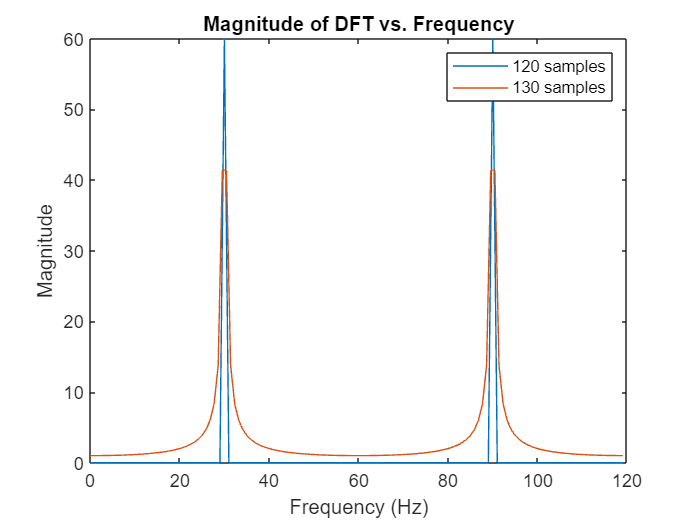

plot(fy,abs(x1))
legend('120 samples','130 samples')
hold off

%question 1.3
alpha=2

alpha = 2

dur=2 %duration of the signal

dur = 2

f=15*alpha %frequency of the signal

f = 30

Fs=120 %sampling frequency

Fs = 120

Ts=1/Fs %sampling period

Ts = 0.0083

t=(0:Ts:dur-Ts) 

t =          0    0.0083    0.0167    0.0250    0.0333    0.0417    0.0500    0.0583    0.0667    0.0750    0.0833    0.0917    0.1000    0.1083    0.1167    0.1250    0.1333    0.1417    0.1500    0.1583    0.1667    0.1750    0.1833    0.1917    0.2000    0.2083    0.2167    0.2250    0.2333    0.2417    0.2500    0.2583    0.2667    0.2750    0.2833    0.2917    0.3000    0.3083    0.3167    0.3250    0.3333    0.3417    0.3500    0.3583    0.3667    0.3750    0.3833    0.3917    0.4000    0.4083


y= sin(2*pi*f*t)

y =          0    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000


len1=120 % first 120 samples

len1 = 120

x=fft(y(1:len1)) % computing fourier transform

x =    0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 -60.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i


fy=(0:len1-1)*Fs/len1 

fy =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(fy,abs(x),'r') % plot
title('Magnitude of DFT vs. Frequency');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on
len2=240 % first 240 samples

len2 = 240

x1=fft(y(1:len2)) % computing fourier transform

x1 = 1.0e+02 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


fy=(0:len2-1)*Fs/len2 

fy =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


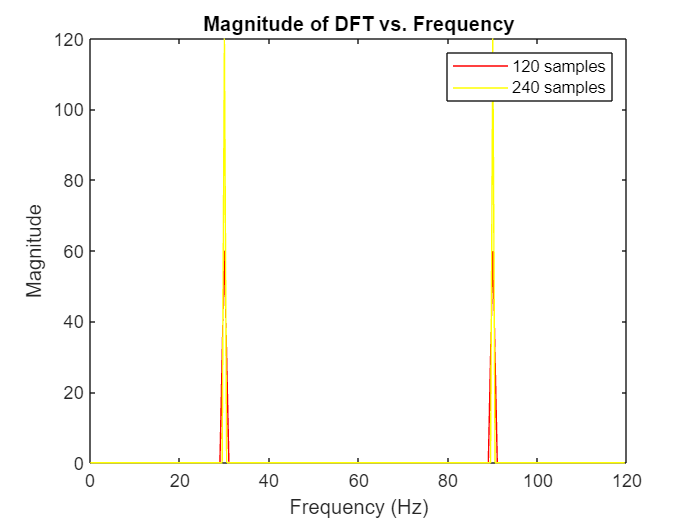

plot(fy,abs(x1),'y') % plot
legend('120 samples','240 samples')
hold off

%question 2
Fs=200

Fs = 200

Ts=1/200

Ts = 0.0050

dur=10

dur = 10

t=(0:Ts:dur-Ts)

t =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


A=140

A = 140

B=146

B = 146

x= 0.1*sin(A*pi*t) + cos(B*pi*t)

x =     1.0000   -0.5804   -0.2204    0.8580   -0.9098    0.3540    0.4269   -0.9100    0.7812   -0.1372   -0.5878    0.9147   -0.6339   -0.0623    0.7117   -0.8877    0.4770    0.2481   -0.8097    0.8369   -0.3090   -0.4281    0.8872   -0.7593    0.1216    0.6071   -0.9392    0.6438    0.0923   -0.7798    0.9511   -0.4780   -0.3307    0.9294   -0.9031    0.2564    0.5786   -1.0304    0.7797    0.0132   -0.8090    1.0568   -0.5769   -0.3078    0.9886   -0.9910    0.3075    0.5930   -1.0872    0.8310


len1=215

len1 = 215

y=fft(x(1:len1))

y =    1.0046 + 0.0000i   1.0047 + 0.0166i   1.0047 + 0.0331i   1.0048 + 0.0497i   1.0049 + 0.0664i   1.0050 + 0.0830i   1.0052 + 0.0998i   1.0054 + 0.1166i   1.0057 + 0.1335i   1.0059 + 0.1505i   1.0063 + 0.1675i   1.0066 + 0.1847i   1.0070 + 0.2021i   1.0074 + 0.2196i   1.0079 + 0.2372i   1.0084 + 0.2550i   1.0089 + 0.2730i   1.0095 + 0.2913i   1.0101 + 0.3097i   1.0108 + 0.3284i   1.0115 + 0.3473i   1.0123 + 0.3665i   1.0131 + 0.3861i   1.0140 + 0.4059i   1.0149 + 0.4261i   1.0159 + 0.4466i   1.0170 + 0.4676i   1.0181 + 0.4889i   1.0193 + 0.5108i   1.0206 + 0.5331i   1.0219 + 0.5559i   1.0233 + 0.5792i   1.0248 + 0.6032i   1.0264 + 0.6278i   1.0281 + 0.6531i   1.0300 + 0.6791i   1.0319 + 0.7059i   1.0339 + 0.7335i   1.0361 + 0.7620i   1.0384 + 0.7915i   1.0409 + 0.8221i   1.0436 + 0.8538i   1.0464 + 0.8868i   1.0494 + 0.9211i   1.0527 + 0.9568i   1.0561 + 0.9942i   1.0599 + 1.0333i   1.0639 + 1.0742i   1.0682 + 1.1173i   1.0729 + 1.1627i


f=(0:len1-1)*Fs/len1

f =          0    0.9302    1.8605    2.7907    3.7209    4.6512    5.5814    6.5116    7.4419    8.3721    9.3023   10.2326   11.1628   12.0930   13.0233   13.9535   14.8837   15.8140   16.7442   17.6744   18.6047   19.5349   20.4651   21.3953   22.3256   23.2558   24.1860   25.1163   26.0465   26.9767   27.9070   28.8372   29.7674   30.6977   31.6279   32.5581   33.4884   34.4186   35.3488   36.2791   37.2093   38.1395   39.0698   40.0000   40.9302   41.8605   42.7907   43.7209   44.6512   45.5814


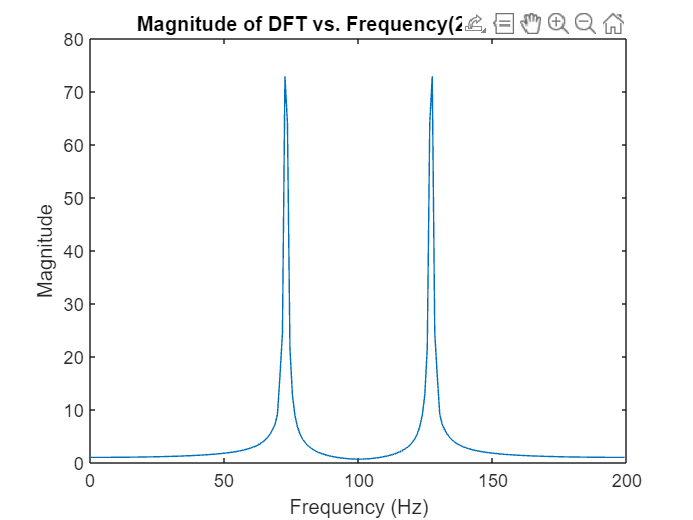

plot(f,abs(y))
title('Magnitude of DFT vs. Frequency(215 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

len2=415

len2 = 415

y2=fft(x(1:len2))

y2 = 1.0e+02 *

   0.0100 + 0.0000i   0.0100 + 0.0001i   0.0100 + 0.0002i   0.0100 + 0.0003i   0.0100 + 0.0003i   0.0100 + 0.0004i   0.0100 + 0.0005i   0.0100 + 0.0006i   0.0100 + 0.0007i   0.0100 + 0.0008i   0.0101 + 0.0009i   0.0101 + 0.0009i   0.0101 + 0.0010i   0.0101 + 0.0011i   0.0101 + 0.0012i   0.0101 + 0.0013i   0.0101 + 0.0014i   0.0101 + 0.0015i   0.0101 + 0.0016i   0.0101 + 0.0016i   0.0101 + 0.0017i   0.0101 + 0.0018i   0.0101 + 0.0019i   0.0101 + 0.0020i   0.0101 + 0.0021i   0.0101 + 0.0022i   0.0101 + 0.0023i   0.0101 + 0.0024i   0.0101 + 0.0025i   0.0101 + 0.0026i   0.0101 + 0.0026i   0.0101 + 0.0027i   0.0101 + 0.0028i   0.0101 + 0.0029i   0.0101 + 0.0030i   0.0101 + 0.0031i   0.0101 + 0.0032i   0.0101 + 0.0033i   0.0101 + 0.0034i   0.0101 + 0.0035i   0.0101 + 0.0036i   0.0101 + 0.0037i   0.0101 + 0.0038i   0.0101 + 0.0039i   0.0101 + 0.0040i   0.0101 + 0.0041i   0.0101 + 0.0042i   0.0102 + 0.0043i   0.0102 + 0.0044i   0.0102 + 0.0045i


f=(0:len2-1)*Fs/len2

f =          0    0.4819    0.9639    1.4458    1.9277    2.4096    2.8916    3.3735    3.8554    4.3373    4.8193    5.3012    5.7831    6.2651    6.7470    7.2289    7.7108    8.1928    8.6747    9.1566    9.6386   10.1205   10.6024   11.0843   11.5663   12.0482   12.5301   13.0120   13.4940   13.9759   14.4578   14.9398   15.4217   15.9036   16.3855   16.8675   17.3494   17.8313   18.3133   18.7952   19.2771   19.7590   20.2410   20.7229   21.2048   21.6867   22.1687   22.6506   23.1325   23.6145


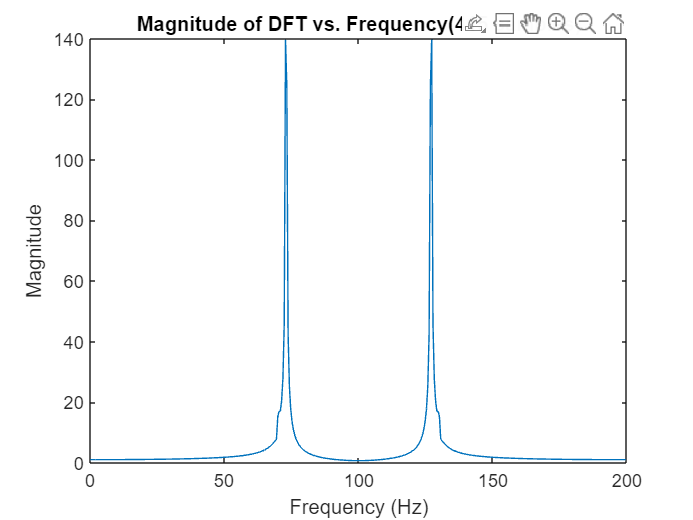

plot(f,abs(y2))
title('Magnitude of DFT vs. Frequency(415 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

len3=1115

len3 = 1115

y3=fft(x(1:len3))

y3 = 1.0e+02 *

  -0.0005 + 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i


f=(0:len3-1)*Fs/len3

f =          0    0.1794    0.3587    0.5381    0.7175    0.8969    1.0762    1.2556    1.4350    1.6143    1.7937    1.9731    2.1525    2.3318    2.5112    2.6906    2.8700    3.0493    3.2287    3.4081    3.5874    3.7668    3.9462    4.1256    4.3049    4.4843    4.6637    4.8430    5.0224    5.2018    5.3812    5.5605    5.7399    5.9193    6.0987    6.2780    6.4574    6.6368    6.8161    6.9955    7.1749    7.3543    7.5336    7.7130    7.8924    8.0717    8.2511    8.4305    8.6099    8.7892


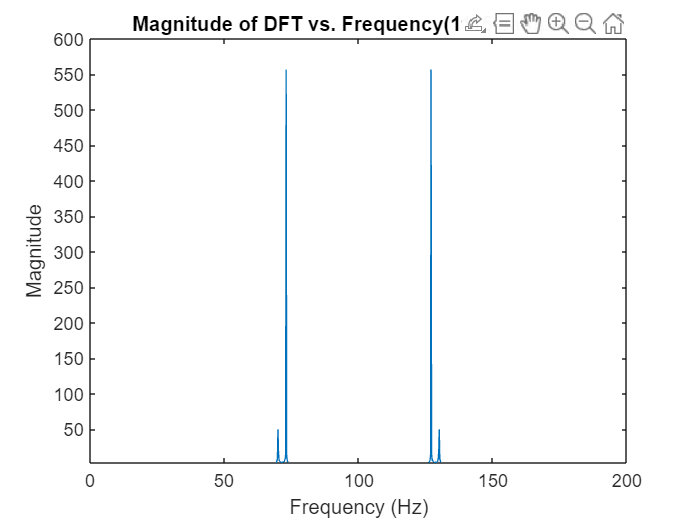

plot(f,abs(y3))
title('Magnitude of DFT vs. Frequency(1115 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

len4=1515

len4 = 1515

y4=fft(x(1:len4))

y4 = 1.0e+02 *

  -0.0005 + 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i


f=(0:len4-1)*Fs/len4

f =          0    0.1320    0.2640    0.3960    0.5281    0.6601    0.7921    0.9241    1.0561    1.1881    1.3201    1.4521    1.5842    1.7162    1.8482    1.9802    2.1122    2.2442    2.3762    2.5083    2.6403    2.7723    2.9043    3.0363    3.1683    3.3003    3.4323    3.5644    3.6964    3.8284    3.9604    4.0924    4.2244    4.3564    4.4884    4.6205    4.7525    4.8845    5.0165    5.1485    5.2805    5.4125    5.5446    5.6766    5.8086    5.9406    6.0726    6.2046    6.3366    6.4686


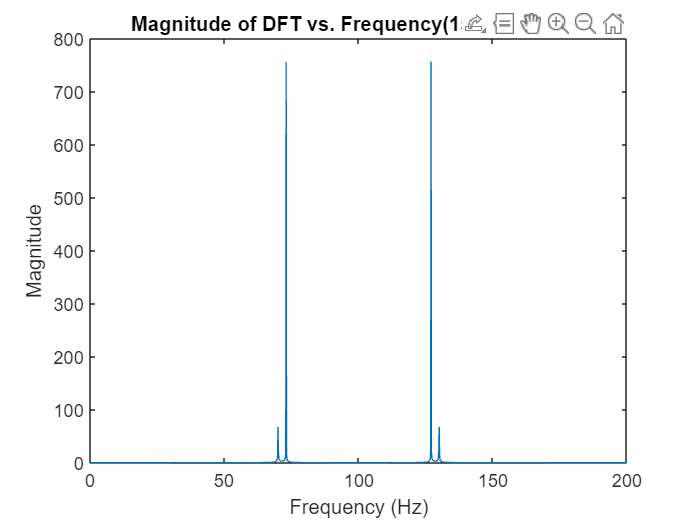

plot(f,abs(y4))
title('Magnitude of DFT vs. Frequency(1515 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

len5=1915

len5 = 1915

y5=fft(x(1:len5))

y5 = 1.0e+02 *

  -0.0005 + 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i  -0.0005 - 0.0000i


f=(0:len5-1)*Fs/len5

f =          0    0.1044    0.2089    0.3133    0.4178    0.5222    0.6266    0.7311    0.8355    0.9399    1.0444    1.1488    1.2533    1.3577    1.4621    1.5666    1.6710    1.7755    1.8799    1.9843    2.0888    2.1932    2.2977    2.4021    2.5065    2.6110    2.7154    2.8198    2.9243    3.0287    3.1332    3.2376    3.3420    3.4465    3.5509    3.6554    3.7598    3.8642    3.9687    4.0731    4.1775    4.2820    4.3864    4.4909    4.5953    4.6997    4.8042    4.9086    5.0131    5.1175


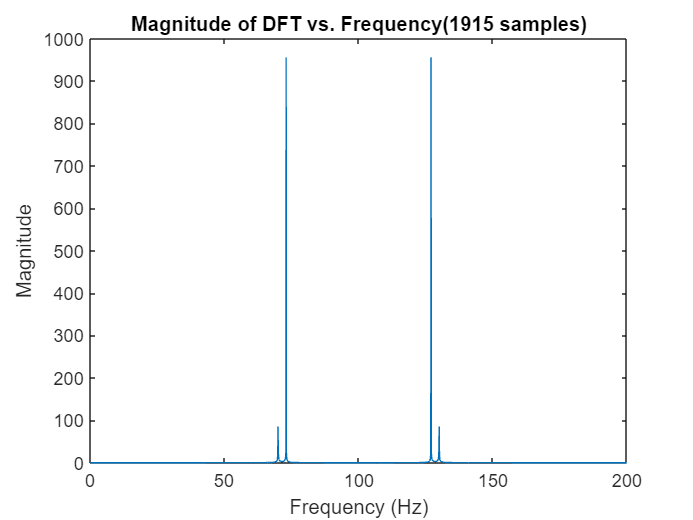

plot(f,abs(y5))
title('Magnitude of DFT vs. Frequency(1915 samples)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

%question 3
len1=[215,415,1115,1515,1915]
for i=1:5
    Fs=200
    Ts=1/200
    dur=10
    t=(0:Ts:dur-Ts)
    A=140
    B=146
    x= 0.1*sin(A*pi*t) + cos(B*pi*t)
    wind= hann(len1(i))
    xa = x(1:len1(i)).*wind';
    y=fft(xa)
    f=(0:len1(i)-1)*Fs/len1(i)
    figure;
    plot(f,abs(y))
    title('Magnitude of DFT vs. Frequency with sample rate=',num2str(len1(i)));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end

%q4
data = load('Exp4Data2.txt');
Fs = 1; 
T=1/Fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (Fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');

[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

%q4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');

[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);






